# External flow analysis

## External energy data analysis

Import interface flow data (5-min)

% interfaceFlow = importInterfaceFlow("D:\EERL\2019_NYISO\2019_Interface_Flow\20190101ExternalLimitsFlows.csv")

**list of interface**

Import/Export proxy (11);

HQ Proxy (3): HQCD (Cedars), HQEX (Import_Export), HQNY (Chateauguay),

NPX Proxy (3): NENP (1385 Northport), NPX-AC (NE-NY), NPX-CSC,

OH Proxy (1): OH-AC, 

PJM Proxy (4): PJDF (Neptune), PJM-AC (PJ-NY, Keystone), PJM-HTP (Hudsuon TP), PJM-VFT (Linden VFT)

% groupsummary(interfaceFlow, "InterfaceName")
% interfaceNames = unique(interfaceFlow.InterfaceName);
% externalIdx = startsWith(string(interfaceNames), "SCH - ");
% externalFlowNames = interfaceNames(externalIdx)
% internalFlowNames = interfaceNames(~externalIdx)

### Import hourly balancing market advisory data

energyFileDir = "D:\EERL\2019_NYISO\2019_Balancing_Market_Advisory\";
energyFileName = "2019*";
energyDataStore = fileDatastore(energyFileDir + energyFileName, "ReadFcn", @importExternalEnergy, "UniformRead", true, "FileExtensions",'.csv');
energyAll = readall(energyDataStore);
clear energyDataStore;

### External energy data cleaning

- 03/10/2019 02:00 data is missing: linear interpolation.

- 11/03/2019 01:00 has duplicates: remove the duplicate record.

variableNames = energyAll.Properties.VariableNames(2:end);
% Clean missing data
beforeMissingTime = datetime('03/10/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
afterMissingTime = datetime('03/10/2019 03:00:01',"Format","MM/dd/uuuu HH:mm:ss");
energyAllMissing = energyAll(energyAll.TimeStamp >= beforeMissingTime & energyAll.TimeStamp < afterMissingTime | ismissing(energyAll.TimeStamp),:);
energyAllAddMissing = array2table(mean(energyAllMissing{:, 2:end}, 1),"VariableNames",variableNames);
TimeStamp = datetime("03/10/2019 02:00:00","Format","MM/dd/uuuu HH:mm:ss");
energyAllAddMissing = addvars(energyAllAddMissing, TimeStamp, 'Before', variableNames(1));
energyAllAddMissing.Properties.VariableNames(2:end) = variableNames;

% Clean duplicated data
dupTime = datetime('11/03/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
energyAllNoDup = energyAll(energyAll.TimeStamp ~= dupTime, :);
energyAllDup = energyAll(energyAll.TimeStamp == dupTime, :);
energyAllRemoveDup = array2table(mean(energyAllDup{:, 2:end}, 1),"VariableNames",variableNames);
TimeStamp = datetime("11/03/2019 01:00:00","Format","MM/dd/uuuu HH:mm:ss");
energyAllRemoveDup = addvars(energyAllRemoveDup, TimeStamp, 'Before', variableNames(1));
energyAllRemoveDup.Properties.VariableNames(2:end) = variableNames;
energyAllCleaned = [energyAllNoDup; energyAllAddMissing; energyAllRemoveDup];
energyAllCleaned = sortrows(energyAllCleaned, "TimeStamp")

energyAllCleaned = 8760×19 table
       TimeStamp        NetImports    DNI_HQ    DNI_NPX    DNI_OH    DNI_PJM    DNI_NYISO    DNI_DELTA    HQProxyDNIHQCD    HQProxyDNIHQEX    HQProxyDNIHQNY    NPXProxyDNINENP    NPXProxyDNINPXAC    NPXProxyDNINPXCSC    OHProxyDNIOHAC    PJMProxyDNIPJDF    PJMProxyDNIPJMAC    PJMProxyDNIPJMHTP    PJMProxyDNIPJMVFT
    ________________    __________    ______    _______    ______    _______    _________    _________    ______________    ______________    ________

#### Create net import table and proxy flow table

netImportAll = energyAllCleaned(:, ["TimeStamp","NetImports","DNI_HQ","DNI_NPX","DNI_OH","DNI_PJM","DNI_NYISO","DNI_DELTA"])

netImportAll = 8760×8 table
       TimeStamp        NetImports    DNI_HQ    DNI_NPX    DNI_OH    DNI_PJM    DNI_NYISO    DNI_DELTA
    ________________    __________    ______    _______    ______    _______    _________    _________

    01/01/2019 00:00       1875         326       -733      1150      1132        1875            0   
    01/01/2019 01:00       1526         229       -628      1150       775        1526         -349   
    01/01/2019 02:00       1187         205       -783      1150       615        1187         -339   
    01/01/2019 03:00       1104         205       -877      1150       626        1104          -83   
    01/01/2019 04:00       1003         205      -1000      1150       648       

netProxyFlowAll = energyAllCleaned(:, [1,2,9:end])

netProxyFlowAll = 8760×13 table
       TimeStamp        NetImports    HQProxyDNIHQCD    HQProxyDNIHQEX    HQProxyDNIHQNY    NPXProxyDNINENP    NPXProxyDNINPXAC    NPXProxyDNINPXCSC    OHProxyDNIOHAC    PJMProxyDNIPJDF    PJMProxyDNIPJMAC    PJMProxyDNIPJMHTP    PJMProxyDNIPJMVFT
    ________________    __________    ______________    ______________    ______________    _______________    ________________    _________________    ______________    _______________    ________________    _________________    _________________

    01/01/2019 00:00       18

#### Plot hourly net imports in 2019

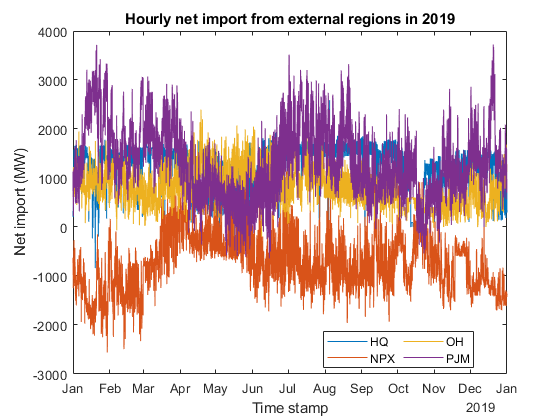

figure;
plot(netImportAll.TimeStamp, netImportAll.DNI_HQ);
hold on;
plot(netImportAll.TimeStamp, netImportAll.DNI_NPX);
plot(netImportAll.TimeStamp, netImportAll.DNI_OH);
plot(netImportAll.TimeStamp, netImportAll.DNI_PJM);
hold off;
legend(["HQ","NPX","OH","PJM"],"Location","best",'NumColumns',2);
xlabel("Time stamp");
ylabel("Net import (MW)");
title("Hourly net import from external regions in 2019");

### Net import daily and monthly summary

netImportDailySum = groupsummary(netImportAll,"TimeStamp","day","sum",["NetImports","DNI_HQ","DNI_NPX","DNI_OH","DNI_PJM","DNI_NYISO","DNI_DELTA"]);
netImportDailySum.day_TimeStamp = datetime(string(netImportDailySum.day_TimeStamp),"InputFormat","dd-MMM-uuuu","Format","MM/dd/uuuu");
netImportDailySum = removevars(netImportDailySum, "GroupCount");
netImportMonthlySum = groupsummary(netImportAll,"TimeStamp","month","sum",["NetImports","DNI_HQ","DNI_NPX","DNI_OH","DNI_PJM","DNI_NYISO","DNI_DELTA"]);
netImportMonthlySum.month_TimeStamp = datetime(string(netImportMonthlySum.month_TimeStamp),"InputFormat","MMM-uuuu","Format","MM/uuuu");
netImportMonthlySum = removevars(netImportMonthlySum, "GroupCount");

#### Plot monthly net import

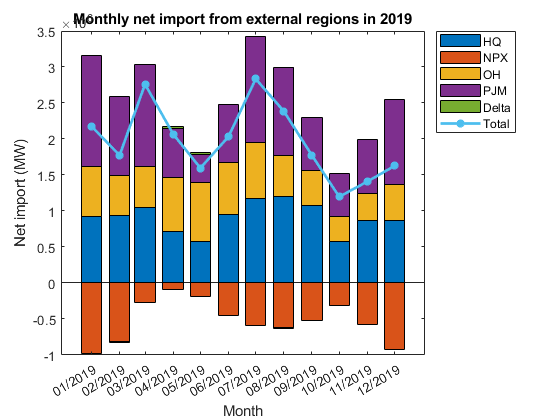

figure;
y = table2array(netImportMonthlySum(:, ["sum_DNI_HQ","sum_DNI_NPX","sum_DNI_OH","sum_DNI_PJM","sum_DNI_DELTA"]));
bar(netImportMonthlySum.month_TimeStamp, y, 'stacked');
hold on;
plot(netImportMonthlySum.month_TimeStamp, netImportMonthlySum.sum_NetImports,"*-","LineWidth",2);
hold off;
legend(["HQ","NPX","OH","PJM","Delta","Total"],"Location","bestoutside");
xlabel("Month");
ylabel("Net import (MW)");
title("Monthly net import from external regions in 2019");

#### Plot daily net import in Jan

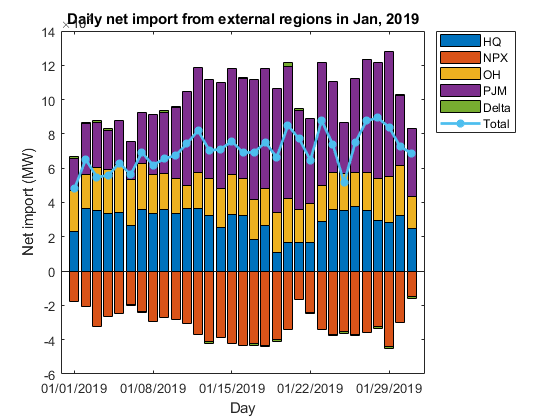

figure;
netImportDailySumJan = netImportDailySum(netImportDailySum.day_TimeStamp.Month == 1, :);
y = table2array(netImportDailySumJan(:, ["sum_DNI_HQ","sum_DNI_NPX","sum_DNI_OH","sum_DNI_PJM","sum_DNI_DELTA"]));
bar(netImportDailySumJan.day_TimeStamp, y, 'stacked');
hold on;
plot(netImportDailySumJan.day_TimeStamp, netImportDailySumJan.sum_NetImports,"*-","LineWidth",2);
hold off;
legend(["HQ","NPX","OH","PJM","Delta","Total"],"Location","bestoutside");
xlabel("Day");
ylabel("Net import (MW)");
title("Daily net import from external regions in Jan, 2019");

### Proxy flow data analysis

proxyNames = string(netProxyFlowAll.Properties.VariableNames(3:end));
proxyNames = extractAfter(proxyNames, 'DNI');
netProxyFlowAll.Properties.VariableNames(3:end) = proxyNames;

#### Plot hourly proxy flow data in 2019

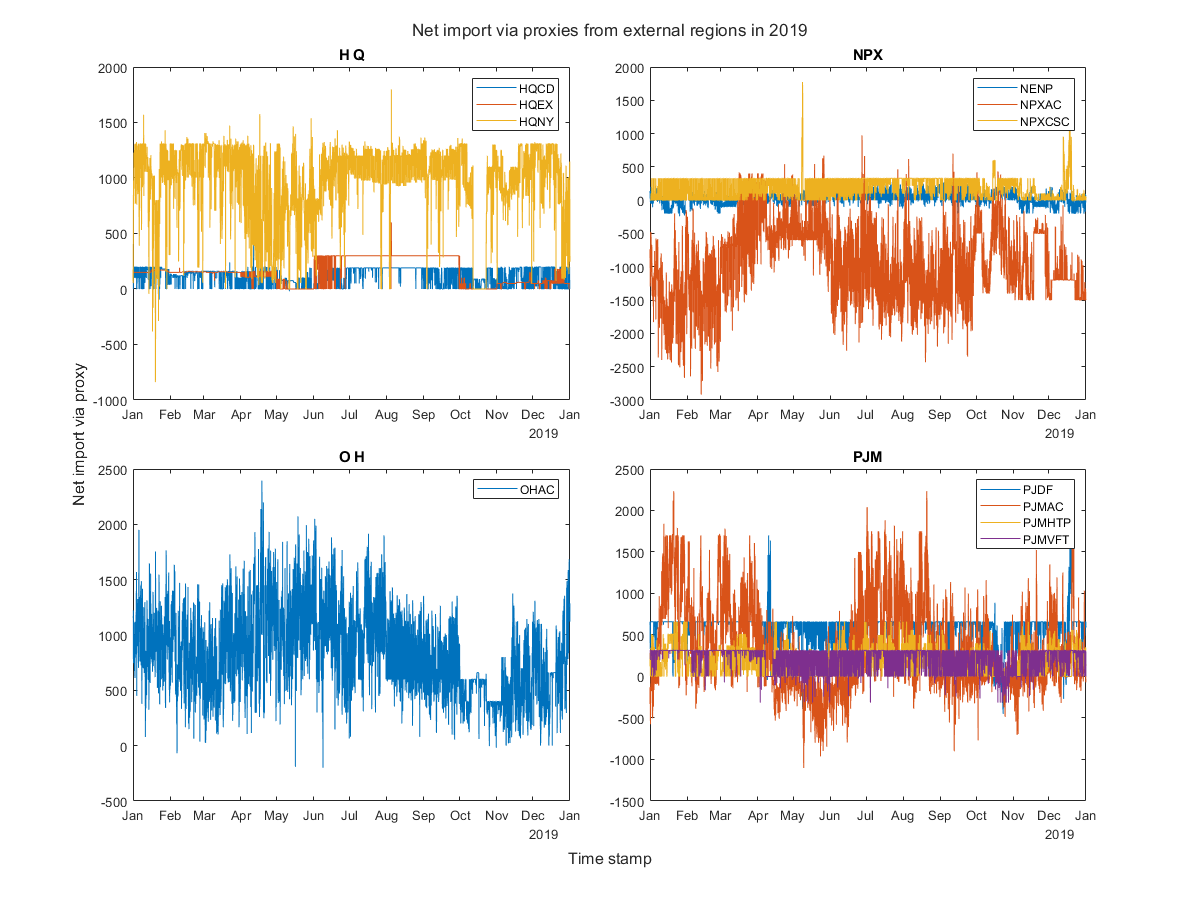

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.HQCD);
hold on;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.HQEX);
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.HQNY);
hold off;
title("H Q");
legend(["HQCD","HQEX","HQNY"]);

nexttile;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.NENP);
hold on;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.NPXAC);
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.NPXCSC);
hold off;
title("NPX");
legend(["NENP","NPXAC","NPXCSC"]);

nexttile;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.OHAC);
title("O H");
legend("OHAC");

nexttile;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.PJDF);
hold on;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.PJMAC);
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.PJMHTP);
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.PJMVFT);
hold off;
title("PJM");
legend(["PJDF","PJMAC","PJMHTP","PJMVFT"]);

xlabel(t, "Time stamp");
ylabel(t, "Net import via proxy");
title(t, "Net import via proxies from external regions in 2019");
set(gcf, "Position", [100, 100, 1200, 900]);

## Price data analysis

### Import DAM zonal price data

% priceFileDir = "D:\EERL\2019_NYISO\2019_DAM_LBMP_Zonal\";
% priceFileName = "2019*";
% energyDataStore = fileDatastore(priceFileDir + priceFileName, "ReadFcn", @importZonalPrice, "UniformRead", true);
% priceAll = readall(energyDataStore);
% clear priceDataStore;
% priceAll

#### Import RTM hourly integrated zonal price data

priceFileDir = "D:\EERL\2019_NYISO\2019_RTM_Integrated_LBMP_Zonal\";
priceFileName = "2019*";
priceDataStore = fileDatastore(priceFileDir + priceFileName, "ReadFcn", @importZonalPrice, "UniformRead", true,"FileExtensions",'.csv');
priceAll = readall(priceDataStore);
clear priceDataStore;

#### Import RTM hourly integrated reference bus price data

priceRefFileDir = "D:\EERL\2019_NYISO\2019_RTM_Integrated_LBMP_Reference_Bus\";
priceRefFileName = "2019*";
priceRefDataStore = fileDatastore(priceRefFileDir + priceRefFileName, "ReadFcn", @importRefPrice, "UniformRead", true,"FileExtensions",'.csv');
priceRefAll = readall(priceRefDataStore);
clear priceRefDataStore;

#### Combine zonal price data with reference bus price data

priceAllWRef = [priceAll; priceRefAll];

#### Price data cleaning

- 03/10/2019 02:00 data is missing: linear interpolation.

- 11/03/2019 01:00 has duplicates: remove the duplicate record.

% Clean missing data
beforeMissingTime = datetime('03/10/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
afterMissingTime = datetime('03/10/2019 03:00:01',"Format","MM/dd/uuuu HH:mm:ss");
priceAllMissing = priceAllWRef(priceAllWRef.TimeStamp >= beforeMissingTime & priceAllWRef.TimeStamp < afterMissingTime | ismissing(priceAllWRef.TimeStamp),:);
priceAllAddMissing = groupsummary(priceAllMissing, ["ZoneName","PTID"],"mean",["LBMP","MarginalCostLosses","MarginalCostCongestion"]);
TimeStamp = datetime(repelem("03/10/2019 02:00:00", 16)',"Format","MM/dd/uuuu HH:mm:ss");
priceAllAddMissing = addvars(priceAllAddMissing, TimeStamp, 'Before', 'ZoneName');
priceAllAddMissing = removevars(priceAllAddMissing, "GroupCount");
priceAllAddMissing.Properties.VariableNames = ["TimeStamp","ZoneName","PTID","LBMP","MarginalCostLosses","MarginalCostCongestion"];

% Clean duplicated data
dupTime = datetime('11/03/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
priceAllNoDup = priceAllWRef(priceAllWRef.TimeStamp ~= dupTime, :);
priceAllDup = priceAllWRef(priceAllWRef.TimeStamp == dupTime, :);
priceAllRemoveDup = groupsummary(priceAllDup, ["ZoneName","PTID"],"mean",["LBMP","MarginalCostLosses","MarginalCostCongestion"]);
TimeStamp = datetime(repelem("11/03/2019 01:00:00", 16)',"Format","MM/dd/uuuu HH:mm:ss");
priceAllRemoveDup = addvars(priceAllRemoveDup, TimeStamp, 'Before', 'ZoneName');
priceAllRemoveDup = removevars(priceAllRemoveDup, "GroupCount");
priceAllRemoveDup.Properties.VariableNames = ["TimeStamp","ZoneName","PTID","LBMP","MarginalCostLosses","MarginalCostCongestion"];
priceAllCleaned = [priceAllNoDup; priceAllAddMissing; priceAllRemoveDup];
priceAllCleaned = sortrows(priceAllCleaned, "TimeStamp");

#### Get a subset of external region price

externalZones = categorical(["H Q","NPX","O H","PJM"]);
priceExternal = priceAllCleaned(ismember(priceAllCleaned.ZoneName, externalZones), :);
priceHQ = priceExternal(priceExternal.ZoneName == "H Q", :);
priceNPX = priceExternal(priceExternal.ZoneName == "NPX", :);
priceOH = priceExternal(priceExternal.ZoneName == "O H", :);
pricePJM = priceExternal(priceExternal.ZoneName == "PJM", :);
priceA = priceAllCleaned(priceAllCleaned.ZoneName == "WEST", :);
priceC = priceAllCleaned(priceAllCleaned.ZoneName == "CENTRL", :);
priceD = priceAllCleaned(priceAllCleaned.ZoneName == "NORTH", :);
priceF = priceAllCleaned(priceAllCleaned.ZoneName == "CAPITL", :);
priceG = priceAllCleaned(priceAllCleaned.ZoneName == "HUD VL", :);
priceJ = priceAllCleaned(priceAllCleaned.ZoneName == "N.Y.C.", :);
priceK = priceAllCleaned(priceAllCleaned.ZoneName == "LONGIL", :);
priceRef = priceAllCleaned(priceAllCleaned.ZoneName == "NYISO_LBMP_REFERENCE", :);

#### Calculate the difference between external LBMP and NYISO reference bus LBMP

priceHQ.diffRef = priceHQ.LBMP - priceRef.LBMP;
priceNPX.diffRef = priceNPX.LBMP - priceRef.LBMP;
priceOH.diffRef = priceOH.LBMP - priceRef.LBMP;
pricePJM.diffRef = pricePJM.LBMP - priceRef.LBMP;

priceHQ.diffD = priceHQ.LBMP - priceD.LBMP;
priceNPX.diffD = priceNPX.LBMP - priceD.LBMP;
priceNPX.diffF = priceNPX.LBMP - priceF.LBMP;
priceNPX.diffG = priceNPX.LBMP - priceG.LBMP;
priceNPX.diffK = priceNPX.LBMP - priceK.LBMP;
priceOH.diffA = priceOH.LBMP - priceA.LBMP;
priceOH.diffD = priceOH.LBMP - priceD.LBMP;
pricePJM.diffA = pricePJM.LBMP - priceA.LBMP;
pricePJM.diffC = pricePJM.LBMP - priceC.LBMP;
pricePJM.diffG = pricePJM.LBMP - priceG.LBMP;
pricePJM.diffJ = pricePJM.LBMP - priceJ.LBMP;
pricePJM.diffK = pricePJM.LBMP - priceK.LBMP;

#### Plot hourly external regions' LBMP and LBMP difference

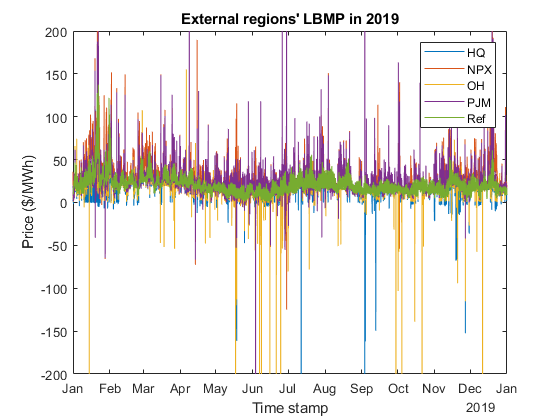

figure;
plot(priceHQ.TimeStamp, priceHQ.LBMP);
hold on;
plot(priceNPX.TimeStamp, priceNPX.LBMP);
plot(priceOH.TimeStamp, priceOH.LBMP);
plot(pricePJM.TimeStamp, pricePJM.LBMP);
plot(priceRef.TimeStamp, priceRef.LBMP);
hold off;
ylabel("Price ($/MWh)");
xlabel("Time stamp");
title("External regions' LBMP in 2019");
legend(["HQ","NPX","OH","PJM","Ref"]);

ylim([-200, 200])

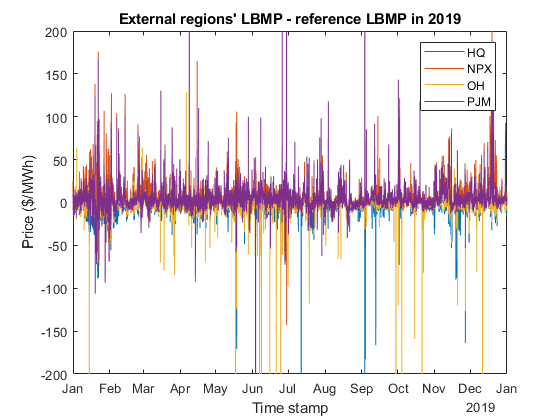

figure;
plot(priceHQ.TimeStamp, priceHQ.diffRef);
hold on;
plot(priceNPX.TimeStamp, priceNPX.diffRef);
plot(priceOH.TimeStamp, priceOH.diffRef);
plot(pricePJM.TimeStamp, pricePJM.diffRef);
hold off;
ylabel("Price ($/MWh)");
xlabel("Time stamp");
title("External regions' LBMP - reference LBMP in 2019");
legend(["HQ","NPX","OH","PJM"]);

ylim([-200, 200])

#### Plot LBMP difference vs net import energy

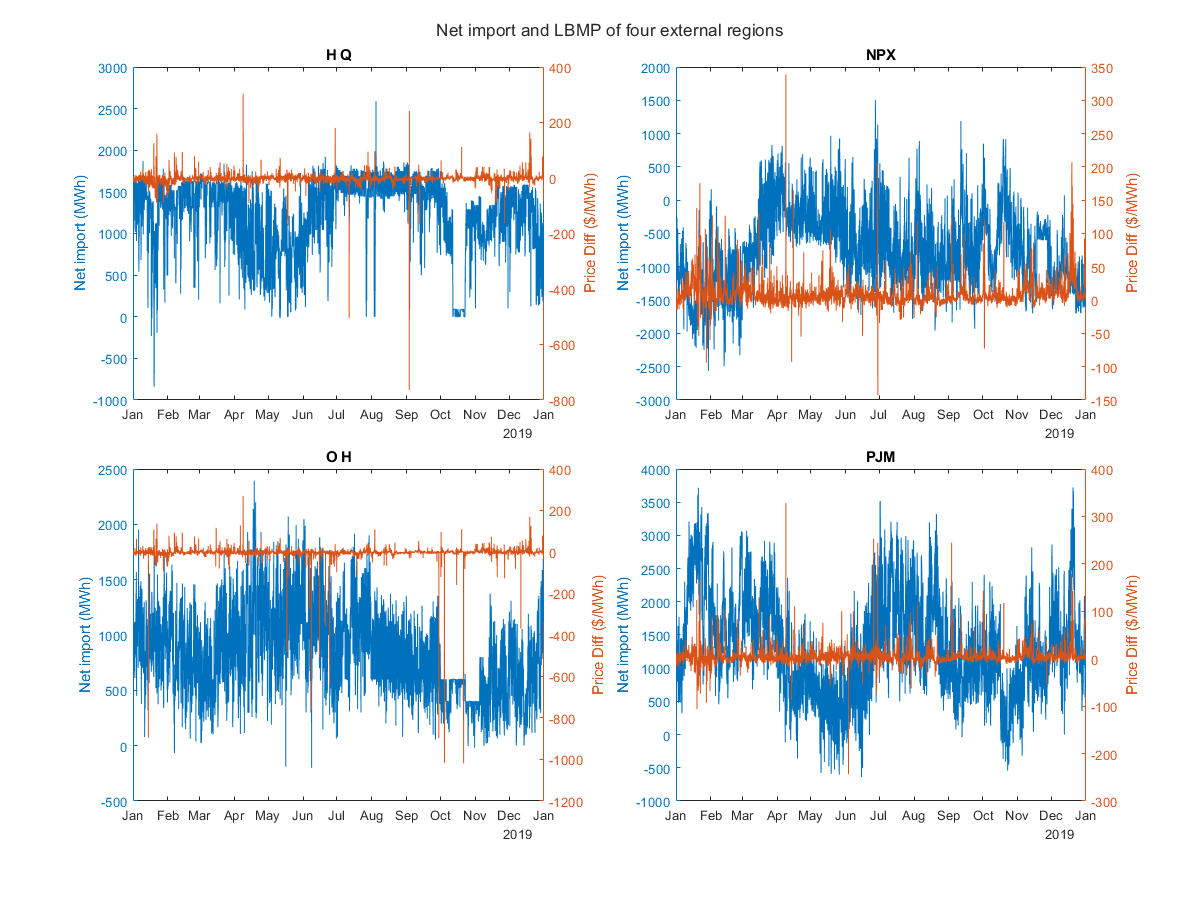

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_HQ);
ylabel("Net import (MWh)");
yyaxis right;
plot(priceHQ.TimeStamp, priceHQ.diffRef);
ylabel("Price Diff ($/MWh)");
title("H Q");

nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_NPX);
ylabel("Net import (MWh)");
yyaxis right;
plot(priceNPX.TimeStamp, priceNPX.diffRef);
ylabel("Price Diff ($/MWh)");
title("NPX");

nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_OH);
ylabel("Net import (MWh)");
yyaxis right;
plot(priceOH.TimeStamp, priceOH.diffRef);
ylabel("Price Diff ($/MWh)");
title("O H");

nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_PJM);
ylabel("Net import (MWh)");
yyaxis right;
plot(pricePJM.TimeStamp, pricePJM.diffRef);
ylabel("Price Diff ($/MWh)");
title("PJM");

title(t, "Net import and LBMP of four external regions");

set(gcf, "Position", [100, 100, 1200, 900]);

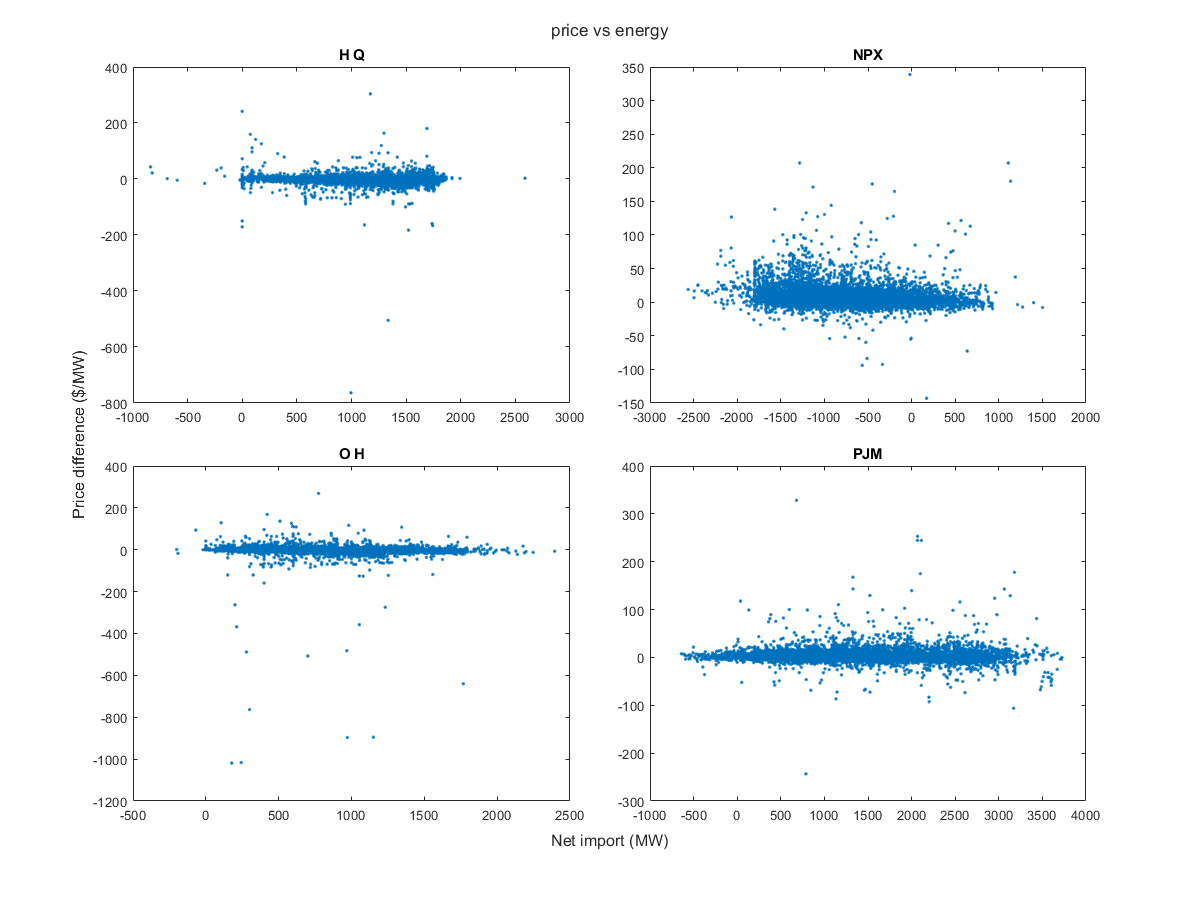

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile;
scatter(netImportAll.DNI_HQ, priceHQ.diffRef, '.');
title("H Q"); box on;

nexttile;
scatter(netImportAll.DNI_NPX, priceNPX.diffRef, '.');
title("NPX"); box on;

nexttile;
scatter(netImportAll.DNI_OH, priceOH.diffRef, '.');
title("O H"); box on;

nexttile;
scatter(netImportAll.DNI_PJM, pricePJM.diffRef, '.');
title("PJM"); box on;

xlabel(t, "Net import (MW)");
ylabel(t, "Price difference ($/MW)")
title(t, "price vs energy");

set(gcf, "Position", [100, 100, 1200, 900]);

#### Price data cleanning

Normalization

priceHQ.priceNorm = normalize(priceHQ.LBMP, 'zscore', 'robust');
priceHQ.diffRefNorm = normalize(priceHQ.diffRef, 'zscore', 'robust');
priceNPX.priceNorm = normalize(priceNPX.LBMP, 'zscore', 'robust');
priceNPX.diffRefNorm = normalize(priceNPX.diffRef, 'zscore', 'robust');
priceOH.priceNorm = normalize(priceOH.LBMP, 'zscore', 'robust');
priceOH.diffRefNorm = normalize(priceOH.diffRef, 'zscore', 'robust');
pricePJM.priceNorm = normalize(pricePJM.LBMP, 'zscore', 'robust');
pricePJM.diffRefNorm = normalize(pricePJM.diffRef, 'zscore', 'robust');

Filling outliers

[priceHQ.priceNormCleaned,outIdxPriceHQ,~,~] = filloutliers(priceHQ.priceNorm,'linear','percentile',[0.1, 99.9]);
[priceHQ.diffRefNormCleaned,outIdxDiffRefHQ,~,~] = filloutliers(priceHQ.diffRefNorm,'linear','percentile',[0.1, 99.9]);
[priceNPX.priceNormCleaned,outIdxPriceNPX,~,~] = filloutliers(priceNPX.priceNorm,'linear','percentile',[0.1, 99.9]);
[priceNPX.diffRefNormCleaned,outIdxDiffRefNPX,~,~] = filloutliers(priceNPX.diffRefNorm,'linear','percentile',[0.1, 99.9]);
[priceOH.priceNormCleaned,outIdxPriceOH,~,~] = filloutliers(priceOH.priceNorm,'linear','percentile',[0.1, 99.9]);
[priceOH.diffRefNormCleaned,outIdxDiffRefOH,~,~] = filloutliers(priceOH.diffRefNorm,'linear','percentile',[0.1, 99.9]);
[pricePJM.priceNormCleaned,outIdxPricePJM,~,~] = filloutliers(pricePJM.priceNorm,'linear','percentile',[0.1, 99.9]);
[pricePJM.diffRefNormCleaned,outIdxDiffRefPJM,~,~] = filloutliers(pricePJM.diffRefNorm,'linear','percentile',[0.1, 99.9]);

% % Fill outliers
% priceHQOriginal = priceHQ.priceNorm;
% [priceHQCleaned,outlierIndices,thresholdLow,thresholdHigh] = ...
%     filloutliers(priceHQOriginal,'linear','percentile',[0.1, 99.9]);
% 
% % Display results
% clf
% plot(priceHQ.TimeStamp,priceHQOriginal,'Color',[109 185 226]/255,...
%     'DisplayName','Input data')
% hold on
% plot(priceHQ.TimeStamp,priceHQCleaned,'Color',[0 114 189]/255,'LineWidth',1.5,...
%     'DisplayName','Cleaned data')
% 
% % Plot outliers
% plot(priceHQ.TimeStamp(outlierIndices),priceHQOriginal(outlierIndices),'x',...
%     'Color',[64 64 64]/255,'DisplayName','Outliers')
% title(['Number of outliers: ' num2str(nnz(outlierIndices))])
% 
% % Plot filled outliers
% plot(priceHQ.TimeStamp(outlierIndices),priceHQCleaned(outlierIndices),'.',...
%     'MarkerSize',12,'Color',[217 83 25]/255,'DisplayName','Filled outliers')
% yline(thresholdLow);
% yline(thresholdHigh);
% hold off
% legend("Location","bestoutside")
% clear outlierIndices thresholdLow thresholdHigh

#### Normalize price form Modi's paper

% priceOH.Zscore = zscore(priceOH.LBMP);
% priceOH.priceScaled = exp(priceOH.Zscore)./(1+exp(priceOH.Zscore)) * (median(priceOH.LBMP) - min(priceOH.LBMP)) + min(priceOH.LBMP);
% priceHQ.Zscore = zscore(priceHQ.LBMP);
% priceHQ.priceScaled = exp(priceHQ.Zscore)./(1+exp(priceHQ.Zscore)) * (median(priceHQ.LBMP) - min(priceHQ.LBMP)) + min(priceHQ.LBMP);
% priceNPX.Zscore = zscore(priceNPX.LBMP);
% priceNPX.priceScaled = exp(priceNPX.Zscore)./(1+exp(priceNPX.Zscore)) * (median(priceNPX.LBMP) - min(priceNPX.LBMP)) + min(priceNPX.LBMP);
% pricePJM.Zscore = zscore(pricePJM.LBMP);
% pricePJM.priceScaled = exp(pricePJM.Zscore)./(1+exp(pricePJM.Zscore)) * (median(pricePJM.LBMP) - min(pricePJM.LBMP)) + min(pricePJM.LBMP);
% figure;
% plot(priceOH.TimeStamp, priceOH.priceScaled);
% hold on;
% plot(priceHQ.TimeStamp, priceHQ.priceScaled);
% plot(priceNPX.TimeStamp, priceNPX.priceScaled);
% plot(pricePJM.TimeStamp, pricePJM.priceScaled);
% hold off;
% ylabel("Price scaled ($/MWh)");
% xlabel("Hour");
% title("External regions' scaled LBMP in 2019");
% legend(["OH","HQ","NPX","PJM"]);

#### Energy data cleaning

netImportAll.DNI_HQ_Norm = normalize(netImportAll.DNI_HQ, 'zscore', 'robust');
netImportAll.DNI_NPX_Norm = normalize(netImportAll.DNI_NPX, 'zscore', 'robust');
netImportAll.DNI_OH_Norm = normalize(netImportAll.DNI_OH, 'zscore', 'robust');
netImportAll.DNI_PJM_Norm = normalize(netImportAll.DNI_PJM, 'zscore', 'robust');

netProxyFlowAll.HQCD_Norm = normalize(netProxyFlowAll.HQCD, 'zscore', 'robust');
netProxyFlowAll.HQEX_Norm = normalize(netProxyFlowAll.HQEX, 'zscore', 'robust');
netProxyFlowAll.HQNY_Norm = normalize(netProxyFlowAll.HQNY, 'zscore', 'robust');
netProxyFlowAll.NENP_Norm = normalize(netProxyFlowAll.NENP, 'zscore', 'robust');
netProxyFlowAll.NPXAC_Norm = normalize(netProxyFlowAll.NPXAC, 'zscore', 'robust');
netProxyFlowAll.NPXCSC_Norm = normalize(netProxyFlowAll.NPXCSC, 'zscore', 'robust');
netProxyFlowAll.OHAC_Norm = normalize(netProxyFlowAll.OHAC, 'zscore', 'robust');
netProxyFlowAll.PJDF_Norm = normalize(netProxyFlowAll.PJDF, 'zscore', 'robust');
netProxyFlowAll.PJMAC_Norm = normalize(netProxyFlowAll.PJMAC, 'zscore', 'robust');
netProxyFlowAll.PJMHTP_Norm = normalize(netProxyFlowAll.PJMHTP, 'zscore', 'robust');
netProxyFlowAll.PJMVFT_Norm = normalize(netProxyFlowAll.PJMVFT, 'zscore', 'robust');

#### Plot cleaned normalized LBMP difference vs net import energy

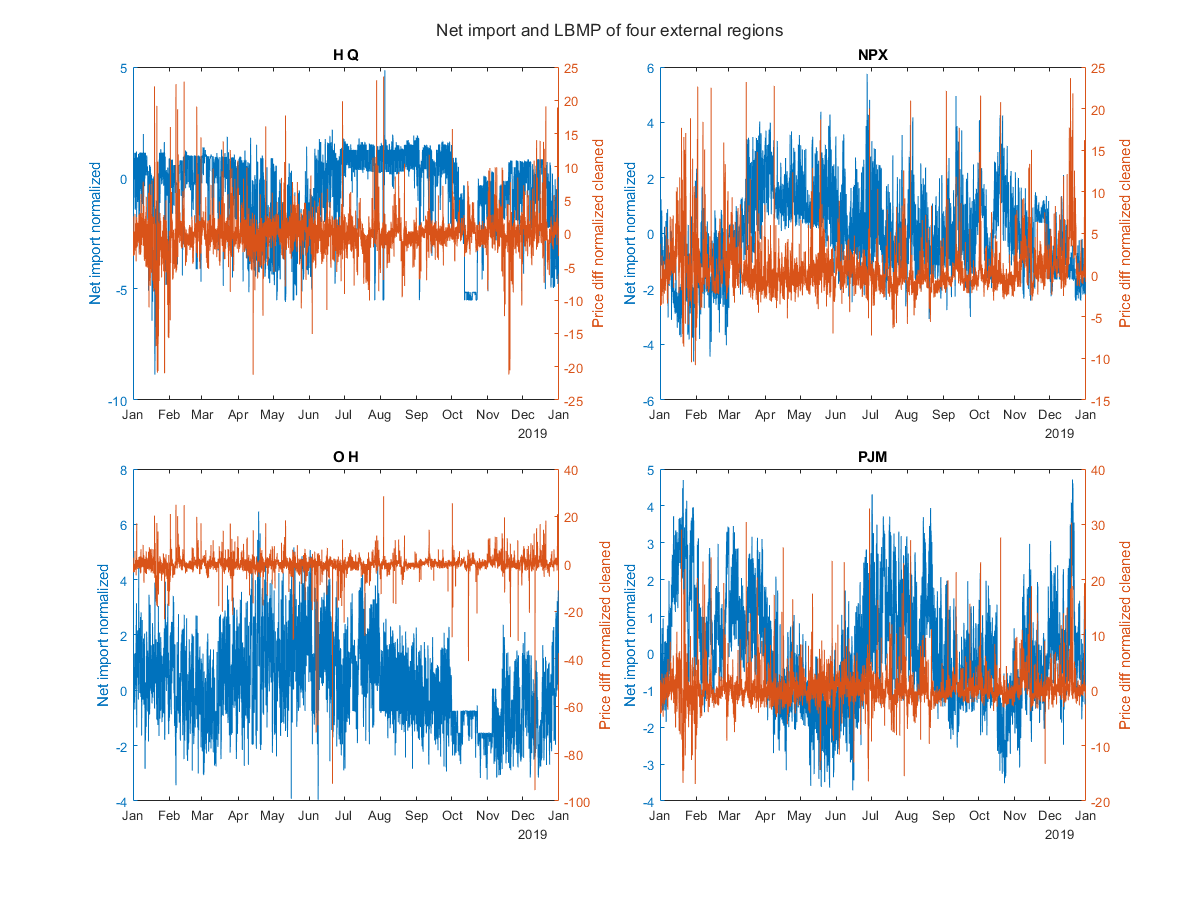

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_HQ_Norm);
ylabel("Net import normalized");
yyaxis right;
plot(priceHQ.TimeStamp, priceHQ.diffRefNormCleaned);
ylabel("Price diff normalized cleaned");
title("H Q");

nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_NPX_Norm);
ylabel("Net import normalized");
yyaxis right;
plot(priceNPX.TimeStamp, priceNPX.diffRefNormCleaned);
ylabel("Price diff normalized cleaned");
title("NPX");

nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_OH_Norm);
ylabel("Net import normalized");
yyaxis right;
plot(priceOH.TimeStamp, priceOH.diffRefNormCleaned);
ylabel("Price diff normalized cleaned");
title("O H");

nexttile;
yyaxis left;
plot(netImportAll.TimeStamp, netImportAll.DNI_PJM_Norm);
ylabel("Net import normalized");
yyaxis right;
plot(pricePJM.TimeStamp, pricePJM.diffRefNormCleaned);
ylabel("Price diff normalized cleaned");
title("PJM");

title(t, "Net import and LBMP of four external regions");

set(gcf, "Position", [100, 100, 1200, 900]);

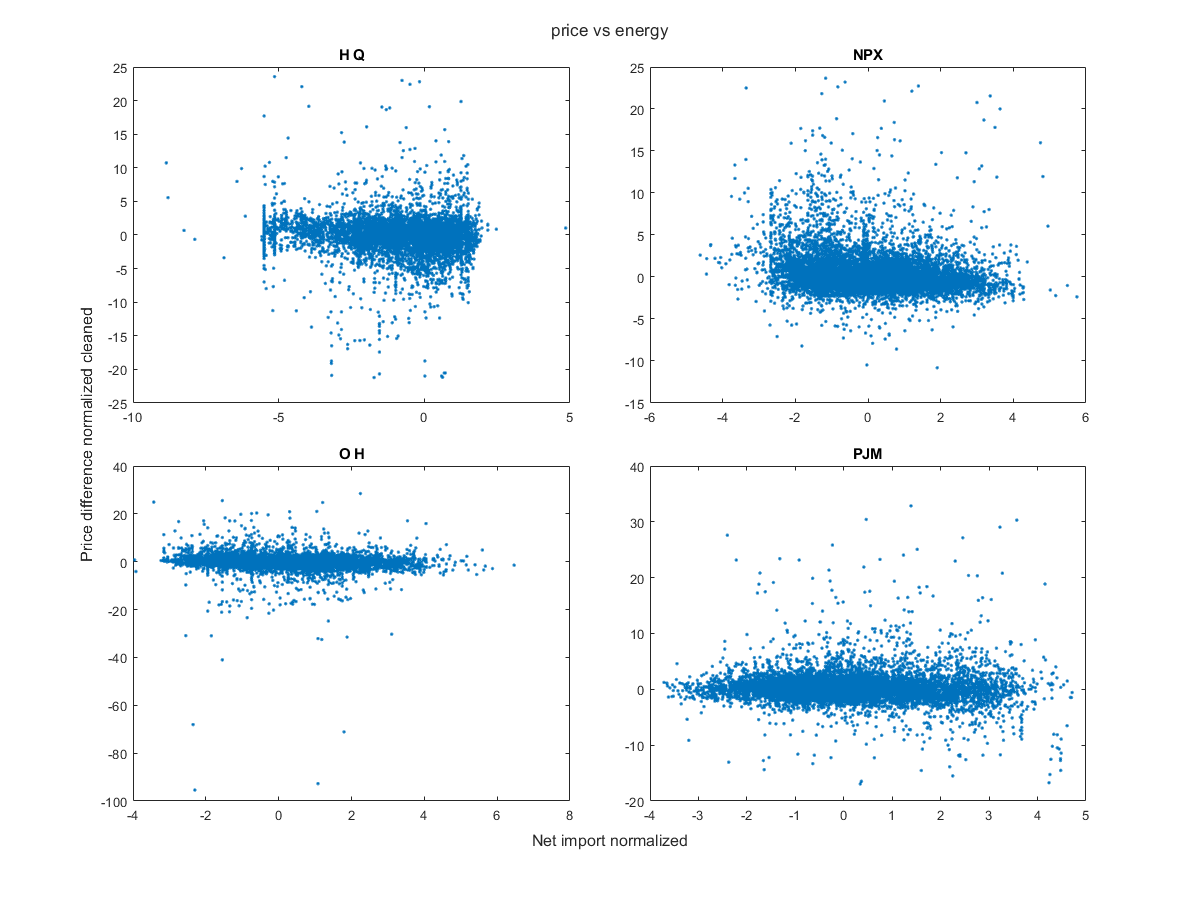

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile;
scatter(netImportAll.DNI_HQ_Norm, priceHQ.diffRefNormCleaned, '.');
title("H Q"); box on;

nexttile;
scatter(netImportAll.DNI_NPX_Norm, priceNPX.diffRefNormCleaned, '.');
title("NPX"); box on;

nexttile;
scatter(netImportAll.DNI_OH_Norm, priceOH.diffRefNormCleaned, '.');
title("O H"); box on;

nexttile;
scatter(netImportAll.DNI_PJM_Norm, pricePJM.diffRefNormCleaned, '.');
title("PJM"); box on;

xlabel(t, "Net import normalized");
ylabel(t, "Price difference normalized cleaned")
title(t, "price vs energy");

set(gcf, "Position", [100, 100, 1200, 900]);

#### Plot hourly proxy flow data vs price

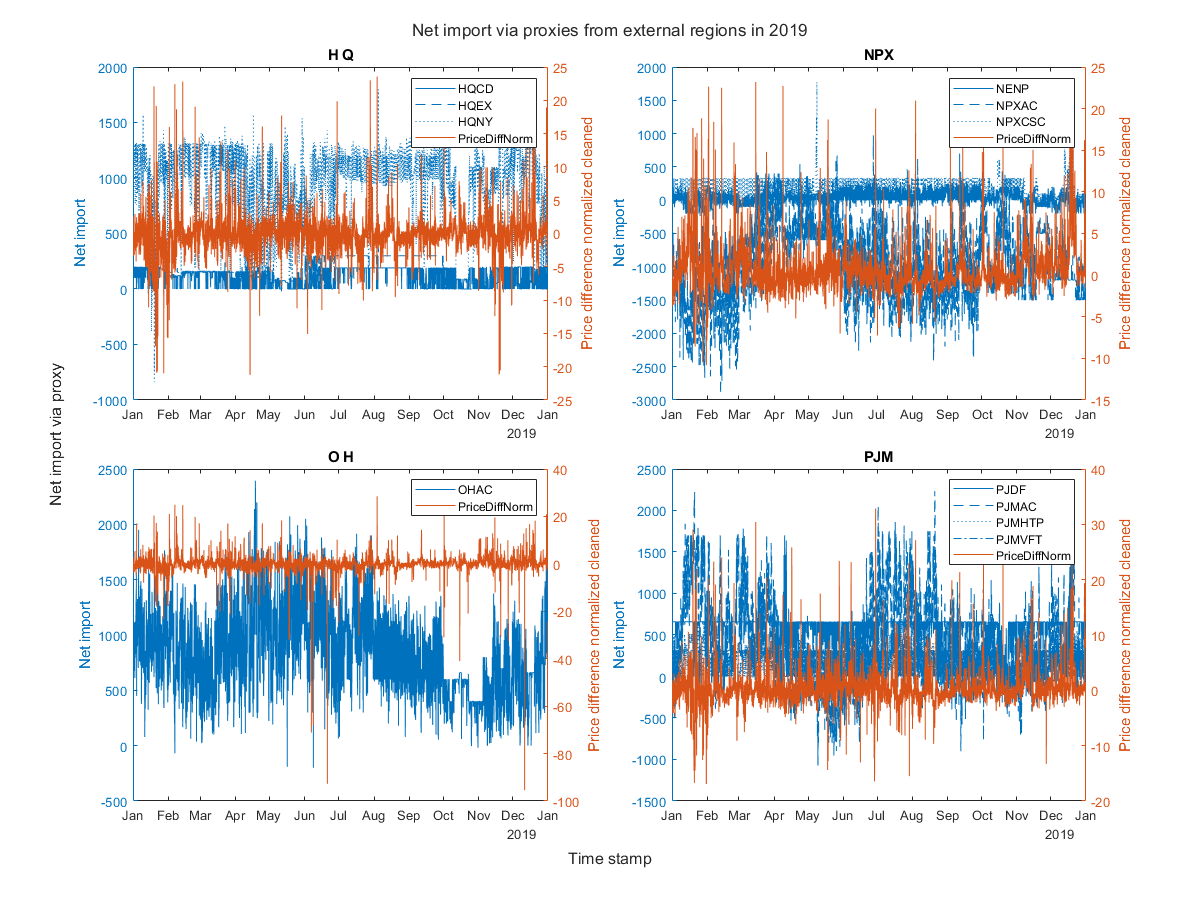

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile;
yyaxis left;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.HQCD);
hold on;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.HQEX);
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.HQNY);
hold off;
ylabel("Net import");
yyaxis right;
plot(priceHQ.TimeStamp, priceHQ.diffRefNormCleaned);
ylabel("Price difference normalized cleaned");
title("H Q");
legend(["HQCD","HQEX","HQNY","PriceDiffNorm"]);

nexttile;
yyaxis left;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.NENP);
hold on;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.NPXAC);
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.NPXCSC);
hold off;
ylabel("Net import");
yyaxis right;
plot(priceNPX.TimeStamp, priceNPX.diffRefNormCleaned);
ylabel("Price difference normalized cleaned");
title("NPX");
legend(["NENP","NPXAC","NPXCSC","PriceDiffNorm"]);

nexttile;
yyaxis left;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.OHAC);
ylabel("Net import");
yyaxis right;
plot(priceOH.TimeStamp, priceOH.diffRefNormCleaned);
ylabel("Price difference normalized cleaned");
title("O H");
legend(["OHAC","PriceDiffNorm"]);

nexttile;
yyaxis left;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.PJDF);
hold on;
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.PJMAC);
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.PJMHTP);
plot(netProxyFlowAll.TimeStamp, netProxyFlowAll.PJMVFT);
hold off;
ylabel("Net import");
yyaxis right;
plot(pricePJM.TimeStamp, pricePJM.diffRefNormCleaned);
ylabel("Price difference normalized cleaned");
title("PJM");
legend(["PJDF","PJMAC","PJMHTP","PJMVFT","PriceDiffNorm"]);

xlabel(t, "Time stamp");
ylabel(t, "Net import via proxy");
title(t, "Net import via proxies from external regions in 2019");

set(gcf, "Position", [100, 100, 1200, 900]);

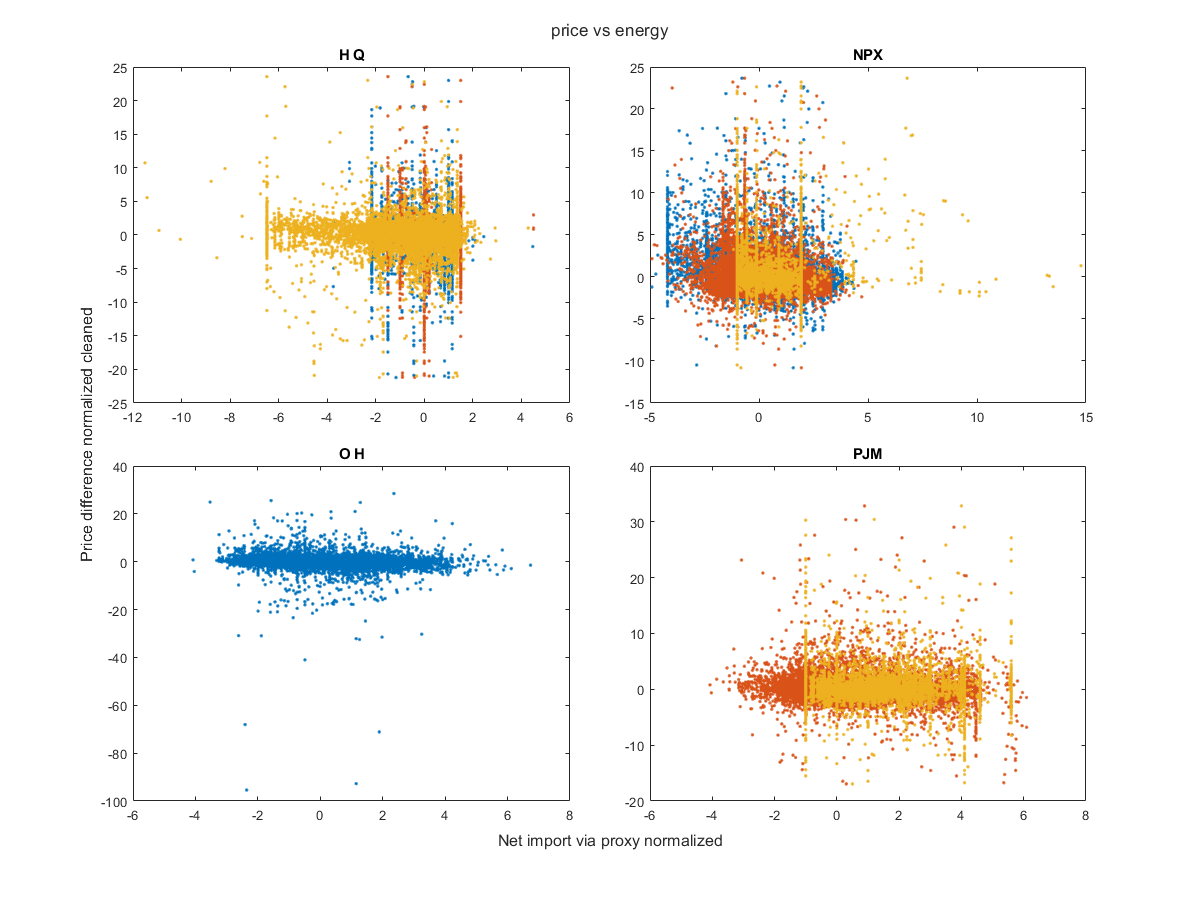

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile; hold on;
scatter(netProxyFlowAll.HQCD_Norm, priceHQ.diffRefNormCleaned, '.');
scatter(netProxyFlowAll.HQEX_Norm, priceHQ.diffRefNormCleaned, '.');
scatter(netProxyFlowAll.HQNY_Norm, priceHQ.diffRefNormCleaned, '.');
title("H Q"); box on; hold off;

nexttile; hold on;
scatter(netProxyFlowAll.NENP_Norm, priceNPX.diffRefNormCleaned, '.');
scatter(netProxyFlowAll.NPXAC_Norm, priceNPX.diffRefNormCleaned, '.');
scatter(netProxyFlowAll.NPXCSC_Norm, priceNPX.diffRefNormCleaned, '.');
title("NPX"); box on; hold off;

nexttile; hold on;
scatter(netProxyFlowAll.OHAC_Norm, priceOH.diffRefNormCleaned, '.');
title("O H"); box on;

nexttile; hold on;
scatter(netProxyFlowAll.PJDF_Norm, pricePJM.diffRefNormCleaned, '.');
scatter(netProxyFlowAll.PJMAC_Norm, pricePJM.diffRefNormCleaned, '.');
scatter(netProxyFlowAll.PJMHTP_Norm, pricePJM.diffRefNormCleaned, '.');
scatter(netProxyFlowAll.PJMVFT_Norm, pricePJM.diffRefNormCleaned, '.');
title("PJM"); box on; hold off;

xlabel(t, "Net import via proxy normalized");
ylabel(t, "Price difference normalized cleaned")
title(t, "price vs energy");

set(gcf, "Position", [100, 100, 1200, 900]);

#### normalized zonal price difference vs normalized net proxy flow

threshold = [1, 99];
priceHQ.diffDNorm = normalize(priceHQ.diffD, 'zscore', 'robust');
[priceHQ.diffDNormCleaned,outIdxDiffDHQ,~,~] = filloutliers(priceHQ.diffDNorm,'linear','percentile',threshold);

priceNPX.diffFNorm = normalize(priceNPX.diffF, 'zscore', 'robust');
[priceNPX.diffFNormCleaned,outIdxDiffFNPX,~,~] = filloutliers(priceNPX.diffFNorm,'linear','percentile',threshold);
priceNPX.diffKNorm = normalize(priceNPX.diffK, 'zscore', 'robust');
[priceNPX.diffKNormCleaned,outIdxDiffKNPX,~,~] = filloutliers(priceNPX.diffKNorm,'linear','percentile',threshold);

priceOH.diffANorm = normalize(priceOH.diffA, 'zscore', 'robust');
[priceOH.diffANormCleaned,outIdxDiffDOH,~,~] = filloutliers(priceOH.diffANorm,'linear','percentile',threshold);

pricePJM.diffKNorm = normalize(pricePJM.diffK, 'zscore', 'robust');
[pricePJM.diffKNormCleaned,outIdxDiffKPJM,~,~] = filloutliers(pricePJM.diffKNorm,'linear','percentile',threshold);
pricePJM.diffGNorm = normalize(pricePJM.diffG, 'zscore', 'robust');
[pricePJM.diffGNormCleaned,outIdxDiffGPJM,~,~] = filloutliers(pricePJM.diffGNorm,'linear','percentile',threshold);
pricePJM.diffJNorm = normalize(pricePJM.diffJ, 'zscore', 'robust');
[pricePJM.diffJNormCleaned,outIdxDiffJPJM,~,~] = filloutliers(pricePJM.diffJNorm,'linear','percentile',threshold);

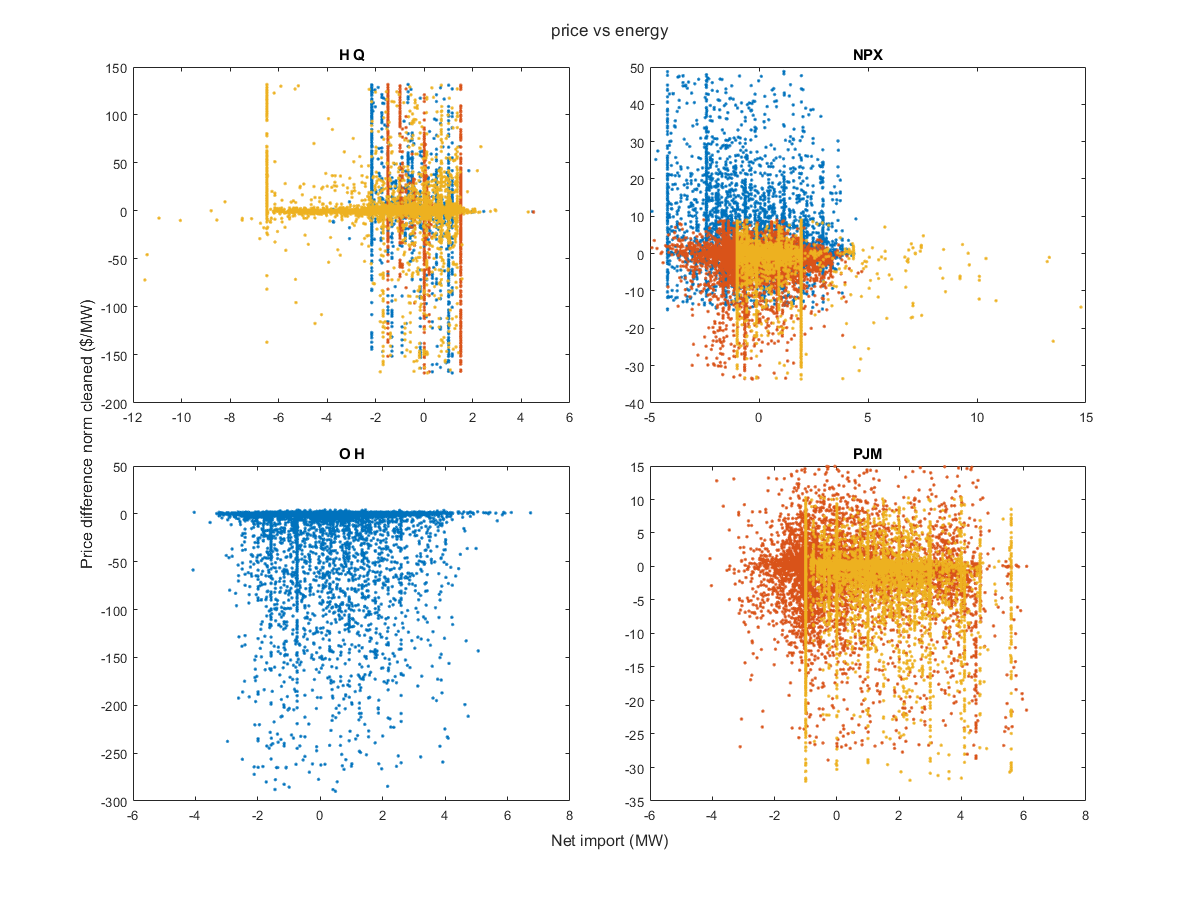

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile; hold on;
scatter(netProxyFlowAll.HQCD_Norm, priceHQ.diffDNormCleaned, '.');
scatter(netProxyFlowAll.HQEX_Norm, priceHQ.diffDNormCleaned, '.');
scatter(netProxyFlowAll.HQNY_Norm, priceHQ.diffDNormCleaned, '.');
title("H Q"); box on; hold off;

nexttile; hold on;
scatter(netProxyFlowAll.NENP_Norm, priceNPX.diffFNormCleaned, '.');
scatter(netProxyFlowAll.NPXAC_Norm, priceNPX.diffKNormCleaned, '.');
scatter(netProxyFlowAll.NPXCSC_Norm, priceNPX.diffKNormCleaned, '.');
title("NPX"); box on; hold off;

nexttile; hold on;
scatter(netProxyFlowAll.OHAC_Norm, priceOH.diffANormCleaned, '.');
title("O H"); box on;

nexttile; hold on;
scatter(netProxyFlowAll.PJDF_Norm, pricePJM.diffKNormCleaned, '.');
scatter(netProxyFlowAll.PJMAC_Norm, pricePJM.diffGNormCleaned, '.');
scatter(netProxyFlowAll.PJMHTP_Norm, pricePJM.diffJNormCleaned, '.');
scatter(netProxyFlowAll.PJMVFT_Norm, pricePJM.diffJNormCleaned, '.');
title("PJM"); box on; hold off;

xlabel(t, "Net import (MW)");
ylabel(t, "Price difference norm cleaned ($/MW)")
title(t, "price vs energy");

set(gcf, "Position", [100, 100, 1200, 900]);

priceOH = 8760×15 table
       TimeStamp        ZoneName    PTID     LBMP     MarginalCostLosses    MarginalCostCongestion    diffRef    diffA    diffD    priceNorm    diffRefNorm    priceNormCleaned    diffRefNormCleaned    diffANorm    diffANormCleaned
    ________________    ________    _____    _____    __________________    ______________________    _______    _____    _____    _________    ___________    ________________    __________________    _________    ________________

   

priceOH